# Problem 7

Part A)

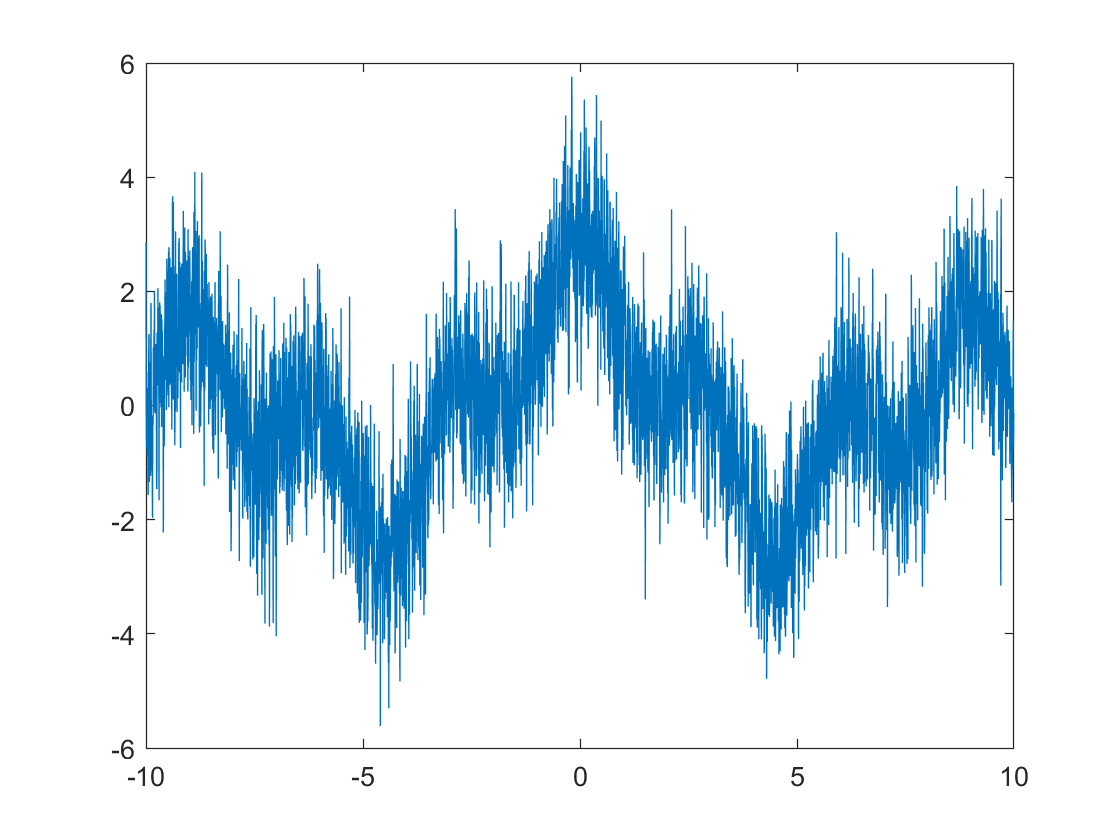

% generate signals
T = 0.005;
Fs = 1/T;
n = -10:T:10-T;
f = (Fs*(0:length(n)-1)/length(n));

x1 = cos(pi*n/6);
x2 = cos(pi*n/4);
x3 = cos(2*pi*n/3);
v = randn(length(n));
v = v(1,:);

x = x1 + x2 + x3 + v;

%plot the output
plot(n, x)

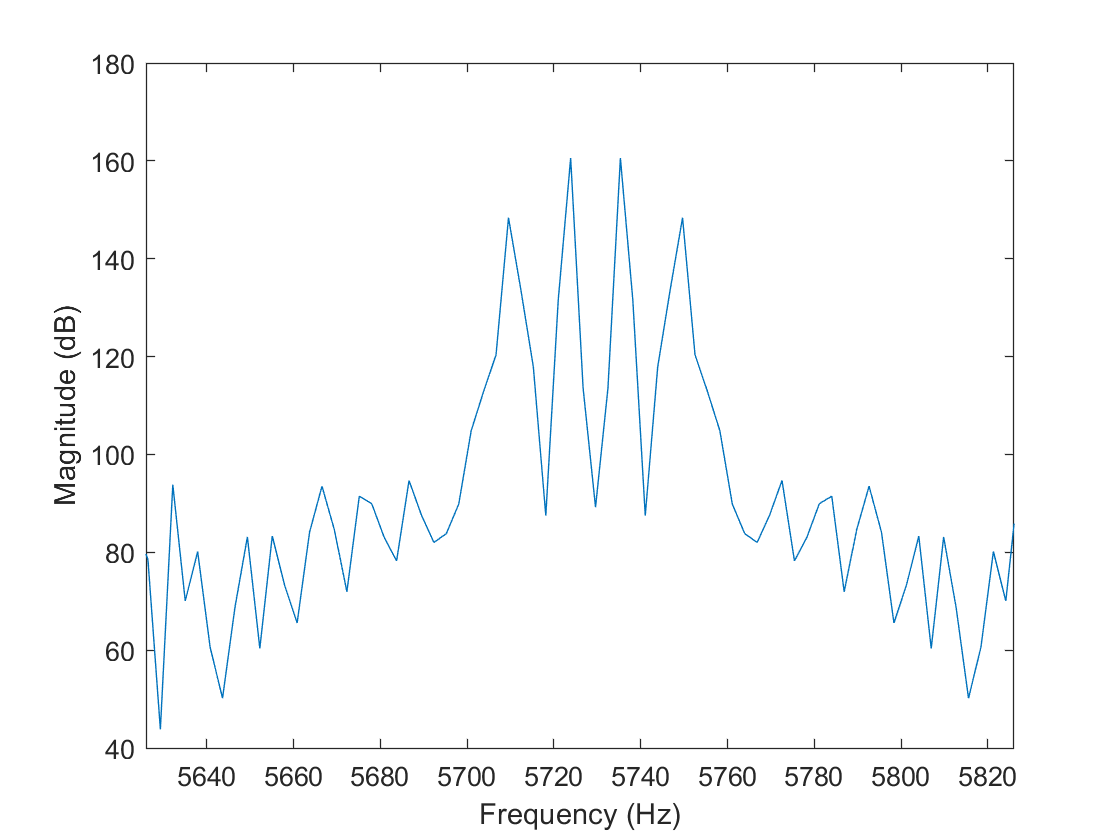

%plot in the frequency domain
X = fft(x);
plot(f*180/pi,20*log(abs(fftshift(X))))
xlabel 'Frequency (Hz)', ylabel 'Magnitude (dB)'
xlim([5726-100, 5726+100])

Create a low pass filter

wp = 1*pi/180 %45 Hz

wp = 0.0175

ws = 25*pi/180 %120 Hz

ws = 0.4363

% wp = (2)*atan(wp*T/2)
% ws = (2)*atan(ws*T/2)

% get the filter order, frequency banned, whether they're pass or stop, and w
[order,fo,ao,w] = firpmord([wp ws],[1 0],[0.0001 0.001],Fs)

order = 1878

fo =          0
    0.0002
    0.0044
    1.0000


ao =      1
     1
     0
     0


w =     10
     1


% calculate the filter
b = firpm(order,fo,ao,w)

b =    -0.0001   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000


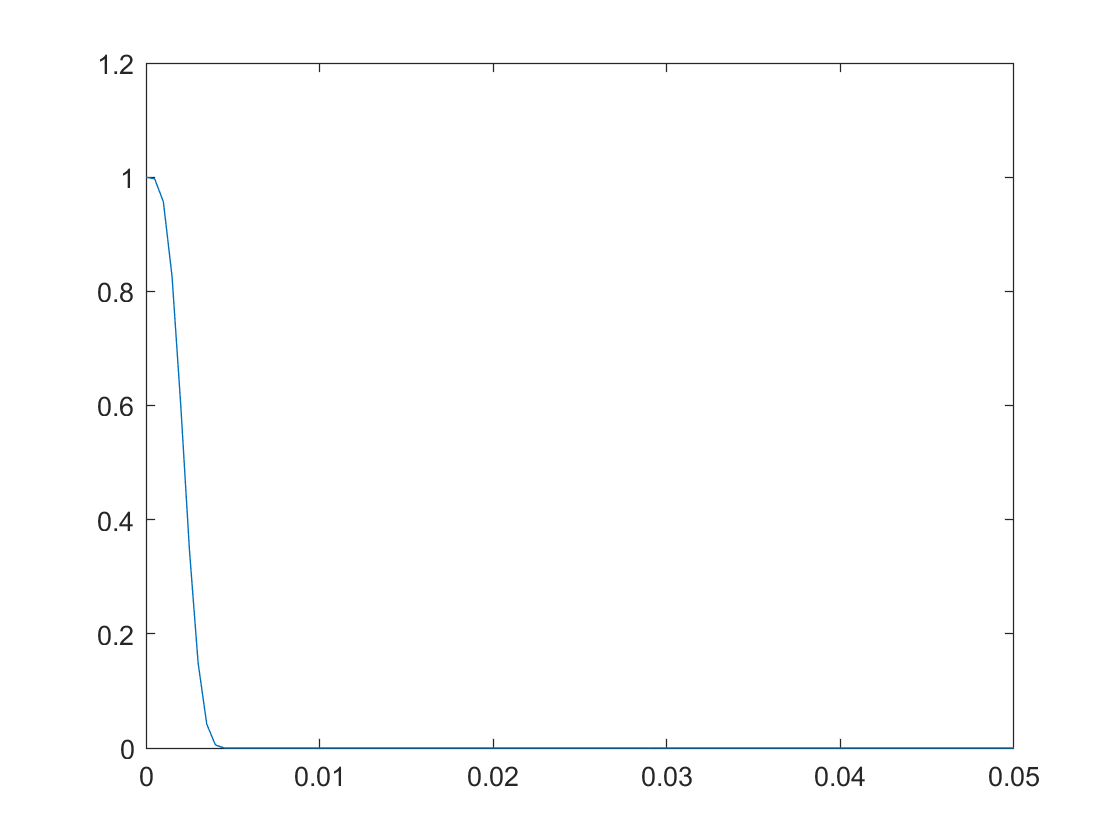

% the last step in calculating a filer
[H,w] = freqz(b,1,length(f)/2);
plot(w/pi,abs(H))
xlim([0, 0.05])

Apply the low pass filter and see its result in the time and frequency domain.

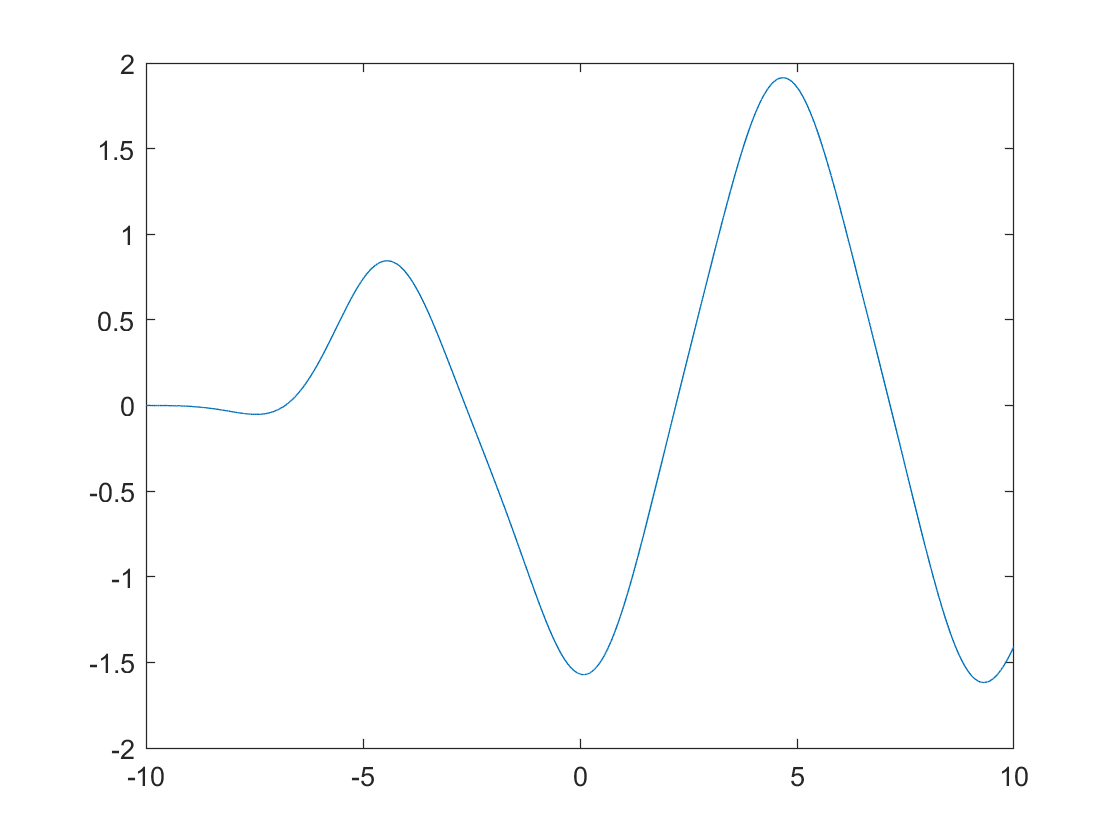

% apply our filter to the signal
y = filter(b,1,x);

% our filtered output
plot(n, y)

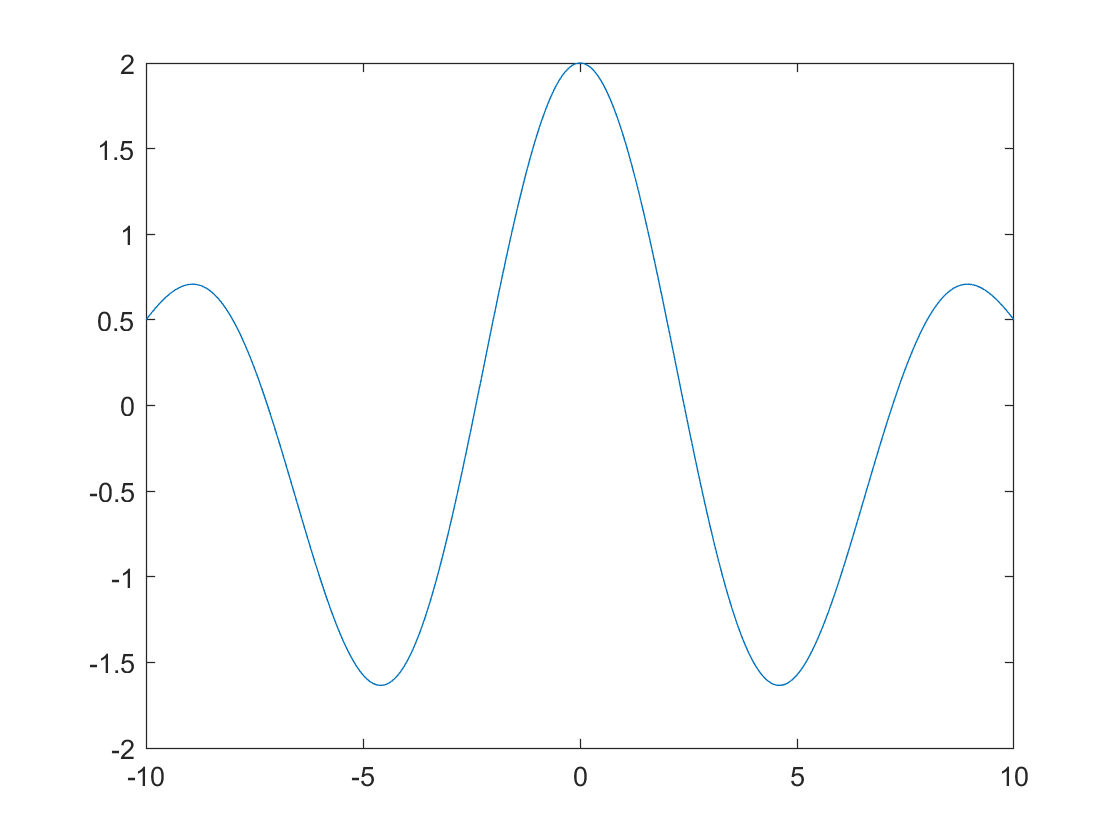

% some other plots for comparison
plot(n, x1 + x2) % the ideal plot

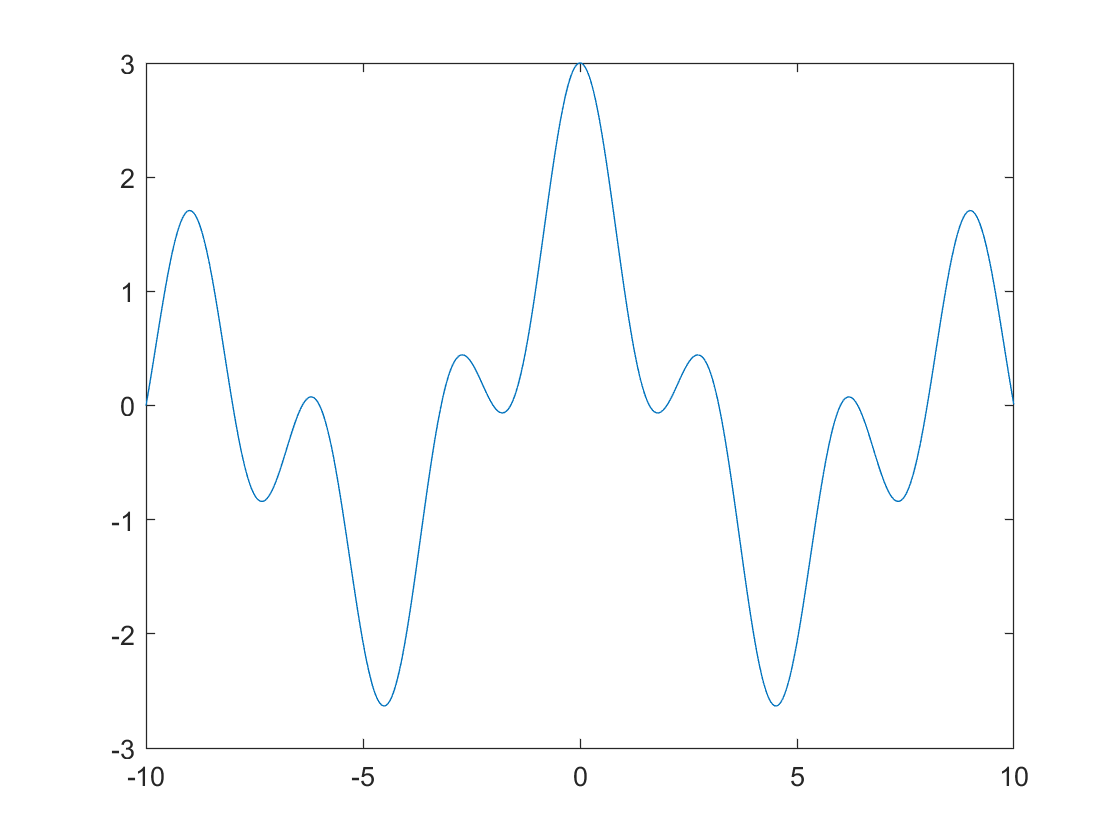

plot(n, x1 + x2 + x3) % the output plot without filtering x3

As can be seen from the final two charts, this filter does a good job at filtering out the noise and x3 from the signal. It just takes the filter a little bit of time to start working correctly (somewhere around n = 0) since the filter frequency is so low.

#### Part B) Designan FIR high pass filter to extract x3

We will begin by constructing our high-pass filter since all of the other signals have been made.

wp = 25*pi/180 % supposed to be 120 Hz

wp = 0.4363

ws = 10*pi/180 % supposed to be 45 Hz

ws = 0.1745


% get the filter order, frequency banned, whether they're pass or stop, and w
[order,fo,ao,w] = firpmord([ws wp],[0 1],[0.01 0.01],Fs)

order = 1486

fo =          0
    0.0017
    0.0044
    1.0000


ao =      0
     0
     1
     1


w =      1
     1


% calculate the filter
b = firpm(order,fo,ao,w)

b =    -0.0068   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000


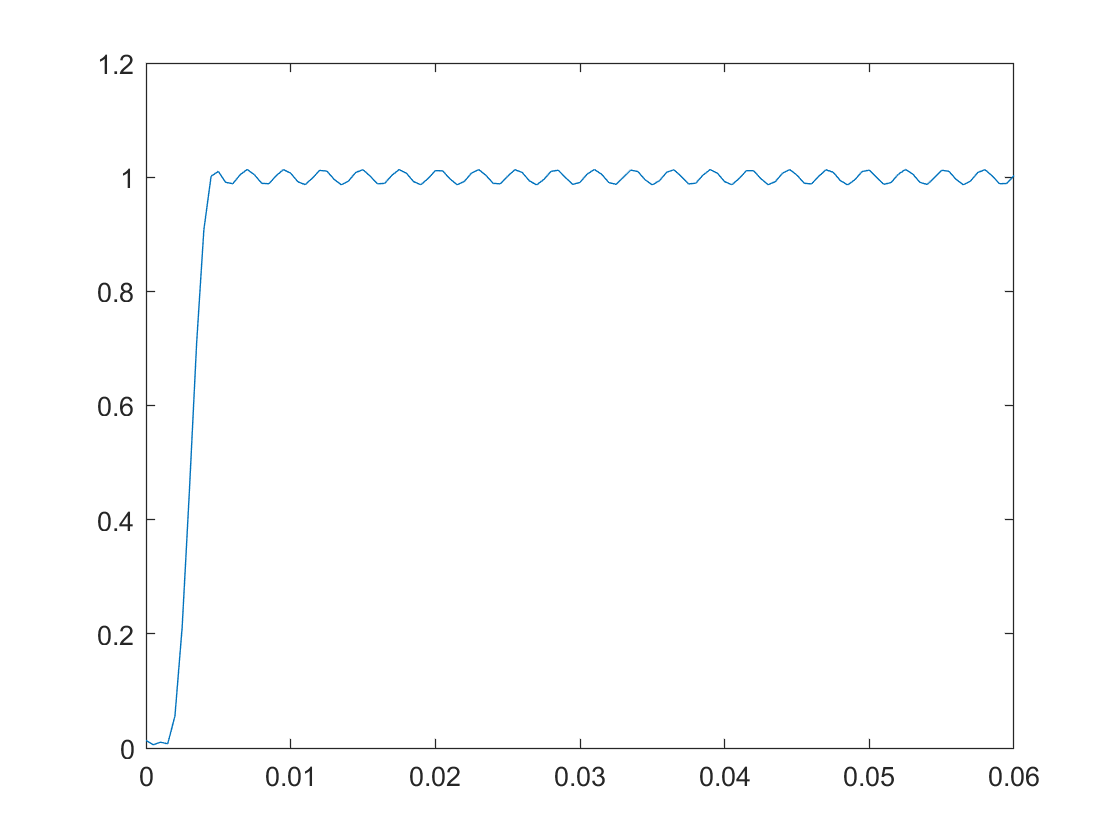

% the last step in calculating a filer
[H,w] = freqz(b,1,length(f)/2);
plot(w/pi, abs(H))
xlim([0, 0.06])

Now we will apply this filter to our input signal

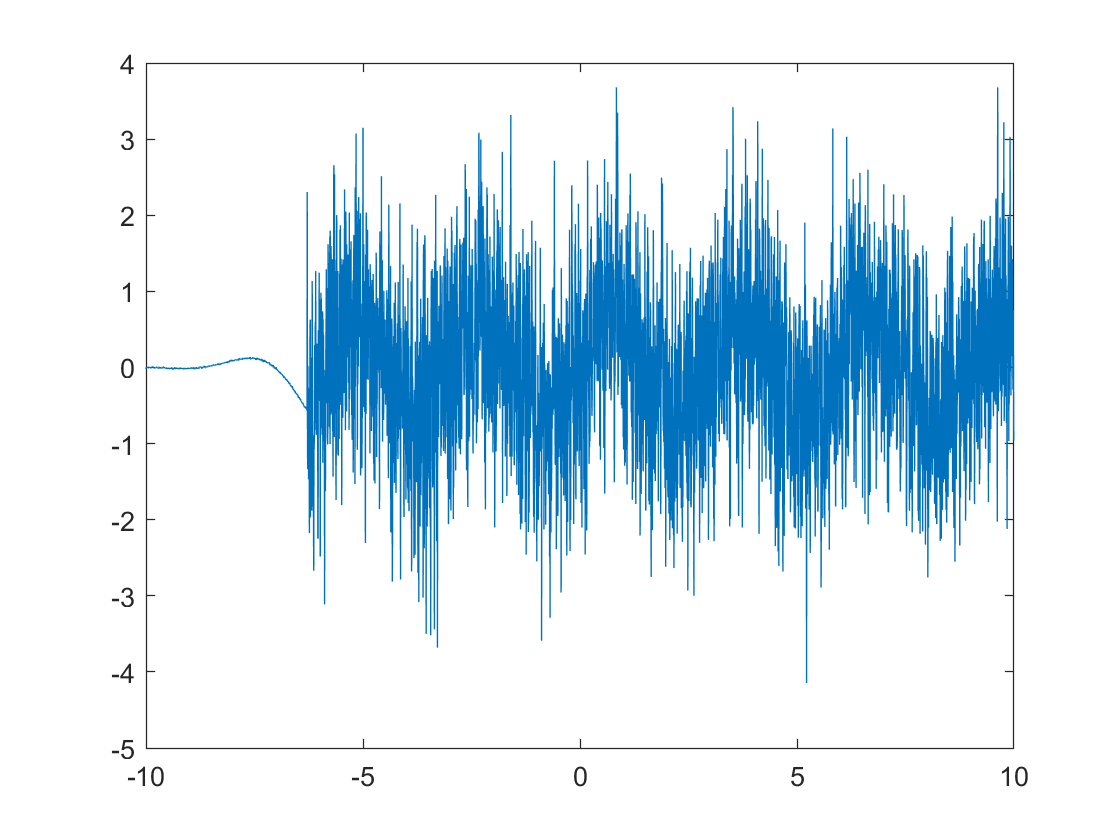

% filter the output
y = filter(b,1,x);

plot(n, y) % the new FILTERED plot

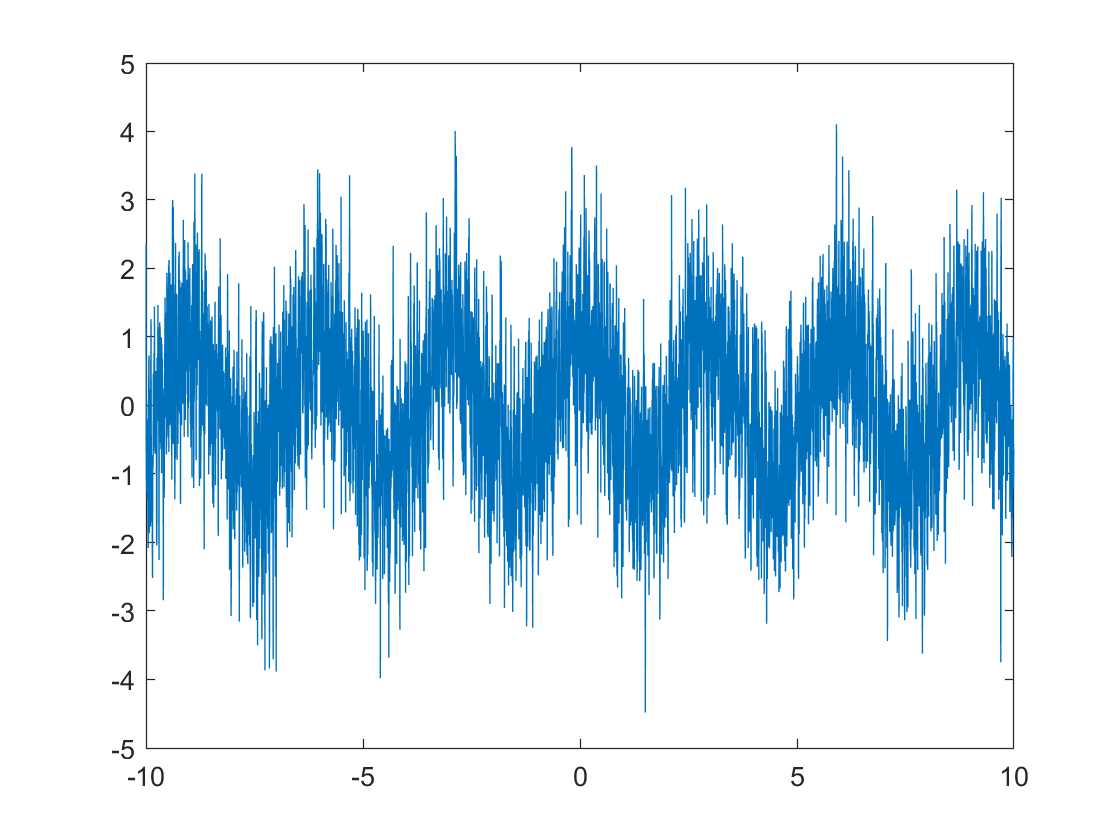

% some other plots for comparison
plot(n, x3 + v) % the ideal plot w/ noise

plot(n, x1 + x2 + x3) % the output plot without filtering x3

A high pass filter is not ideal for this application given that the gaussian noise exists at all frequencies. This means we are still letting through the majority of the noise along with x3. That being said, you can still see the sine wave at the correct frequency and amplitude in the output plot. However, the signal to noise ratio is poor so it is hard to see.

#### Part C) Use Hamming, Blackman, and kaiser windows to extract x1.

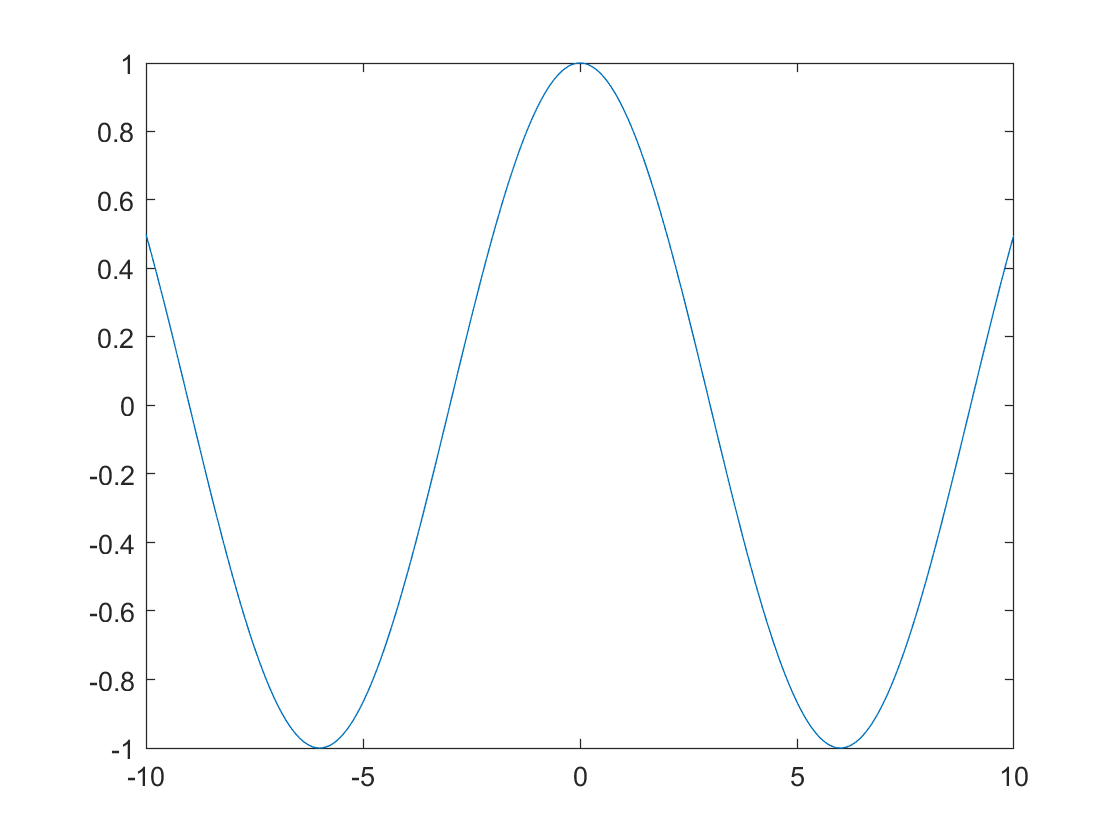

% lets begin by getting a good idea of what x1 looks like:
T = 0.005;
Fs = 1/T;
n = -10:T:10-T;
f = (Fs*(0:length(n)-1)/length(n));
plot(n, x1) % x1 in the time domain

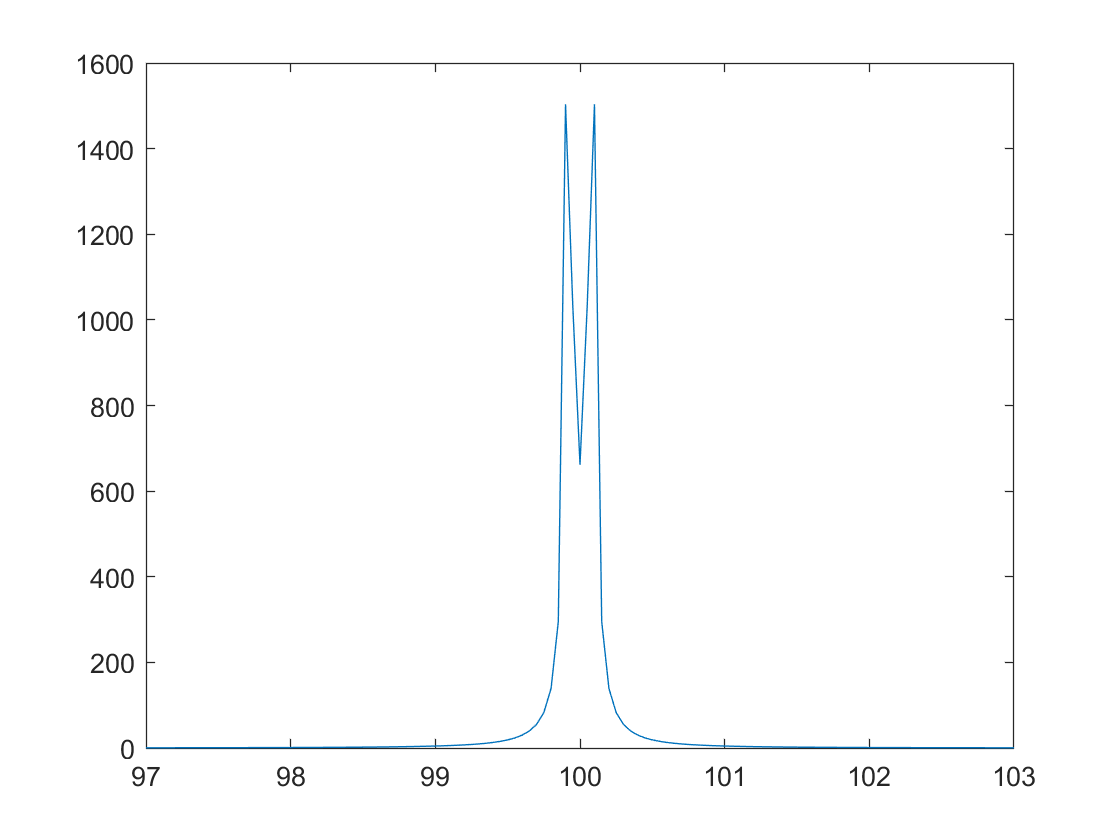

plot(f, abs(fftshift(fft(x1)))) %x1 in the frequency domain
xlim([100-3,100+3])

Next, let's extract x1 using a hamming window

% figure out the filter's parameters
wp = 32*pi/180

wp = 0.5585

ws = pi/4

ws = 0.7854

wp = (2)*atan((wp)*T/2)

wp = 0.0028

ws = (2)*atan((ws)*T/2)

ws = 0.0039

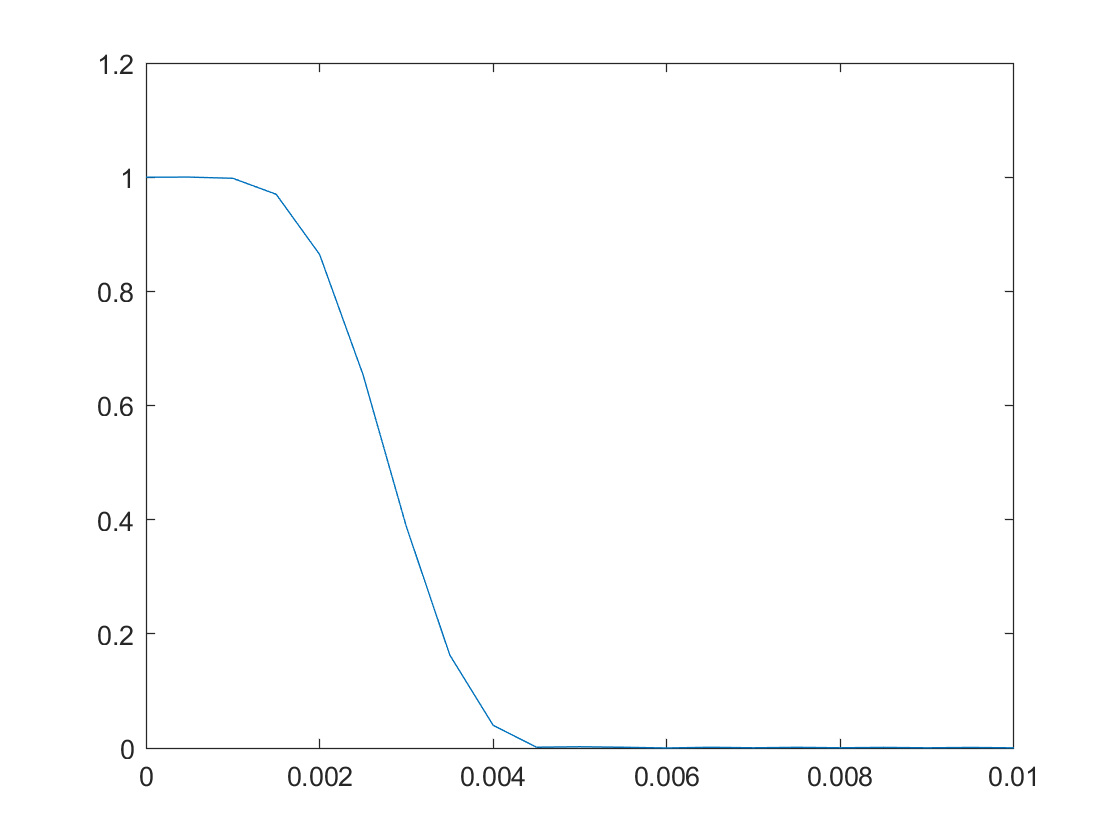


% make the filter
b = fir1(2000,wp,"low"); % creates a low pass hamming filter

% plot the frequency domain
[H,w] = freqz(b,1,length(f)/2);
plot(w/pi, abs(H))
xlim([0, 0.01])


%plot the output signal in the time domain
y = filter(b,1,x)

y =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0000    0.0000    0.0000    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0001    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001


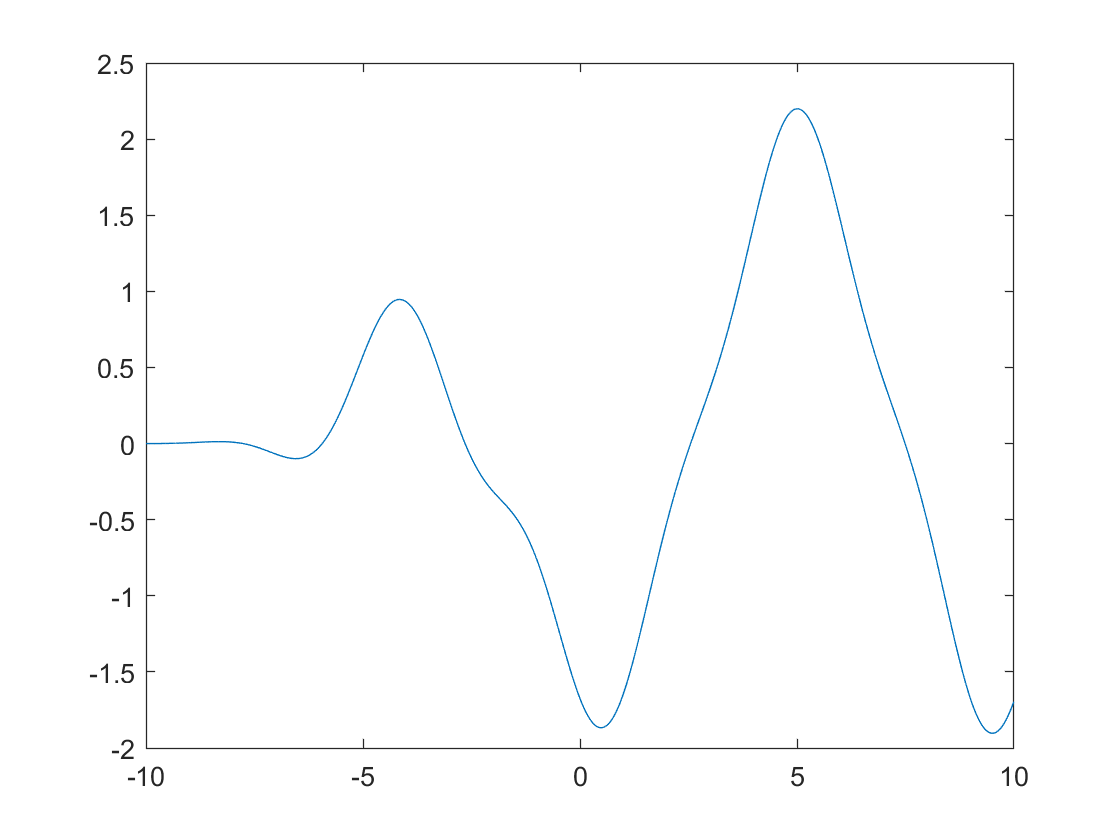

plot(n, y)

%compare that to the ideal signal
plot(n, x1)

This filter does a relatively good job of recovering x1 while ignoring x2, x3, and the noise. 

Now lets extract x1 using a blackman window

% figure out the filter's parameters
n = -10:T:10-T;
wp = (2)*atan((pi/6)*T/2)

wp = 0.0026

ws = (2)*atan((pi/4)*T/2)

ws = 0.0039

wc = (wp + ws) / 2

wc = 0.0033

% we can approximate the window length as M = 8*pi/wc
M = 8*pi / wc

M = 7.6800e+03

alpha = (M-1)/2

alpha = 3.8395e+03

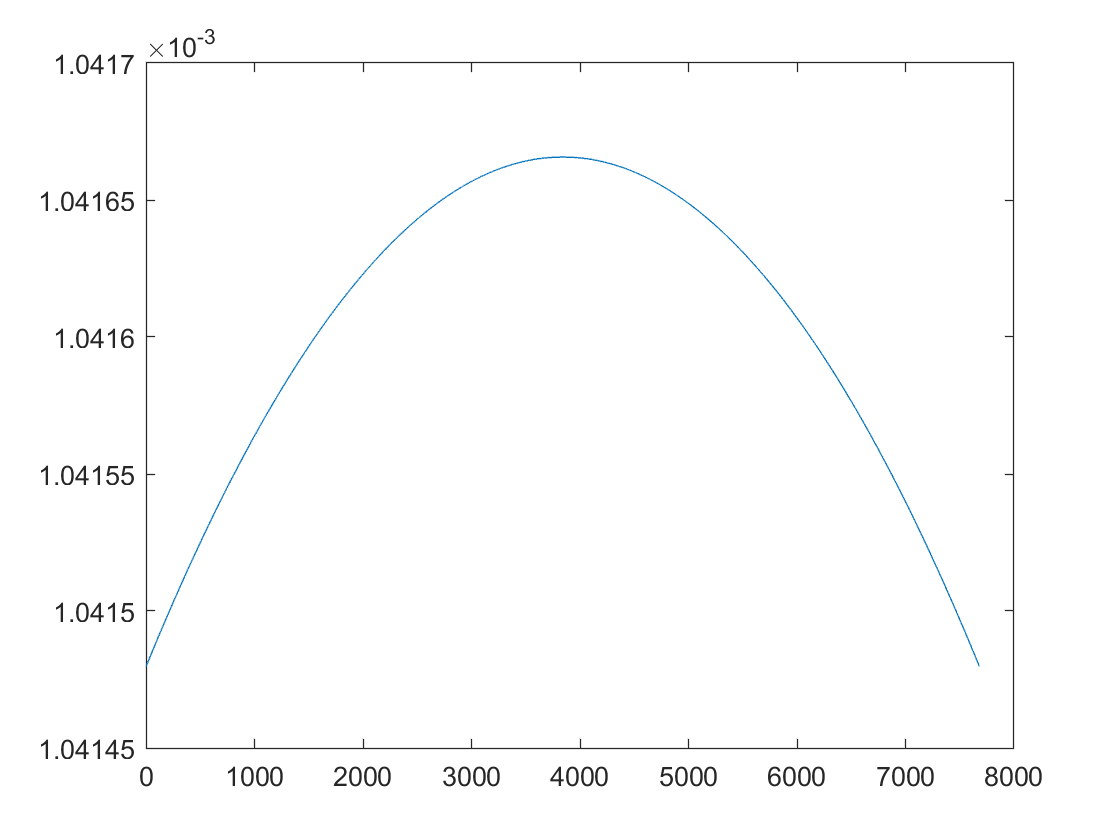



% desired low pass filter
nhd = -10:20/M:10 - 20/M;
hd = (sin(wc*(nhd)))./(pi*(nhd));
plot(hd)

% blackman window
wb = blackman(M);

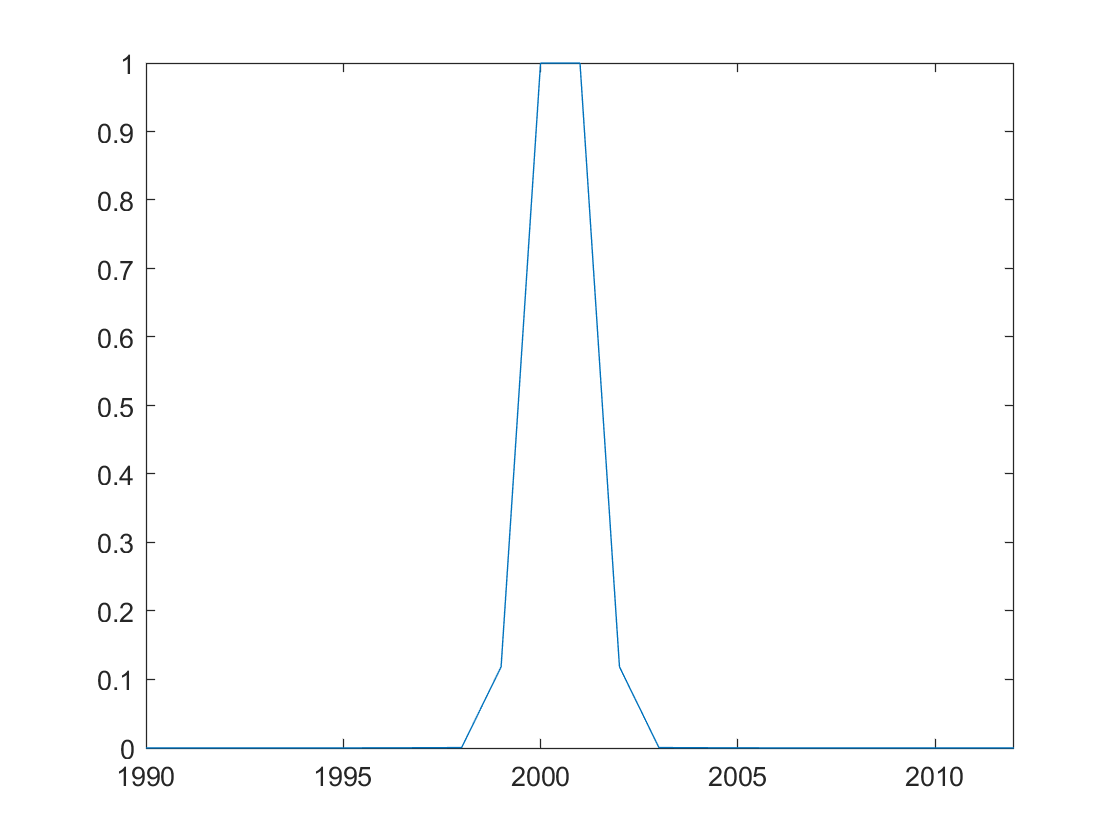

% new blackman low pass filter
hn = wb' .* hd;
% convert to frequency domain
H = freqz(hn,1,length(n)/2);
%convert the filter from the z domain to the frequency domain
H = H';
H = fftshift([fliplr(H) H]/max(H));

% plot the filter
plot(fftshift(abs(H)))
xlim([2001-11,2001+11])

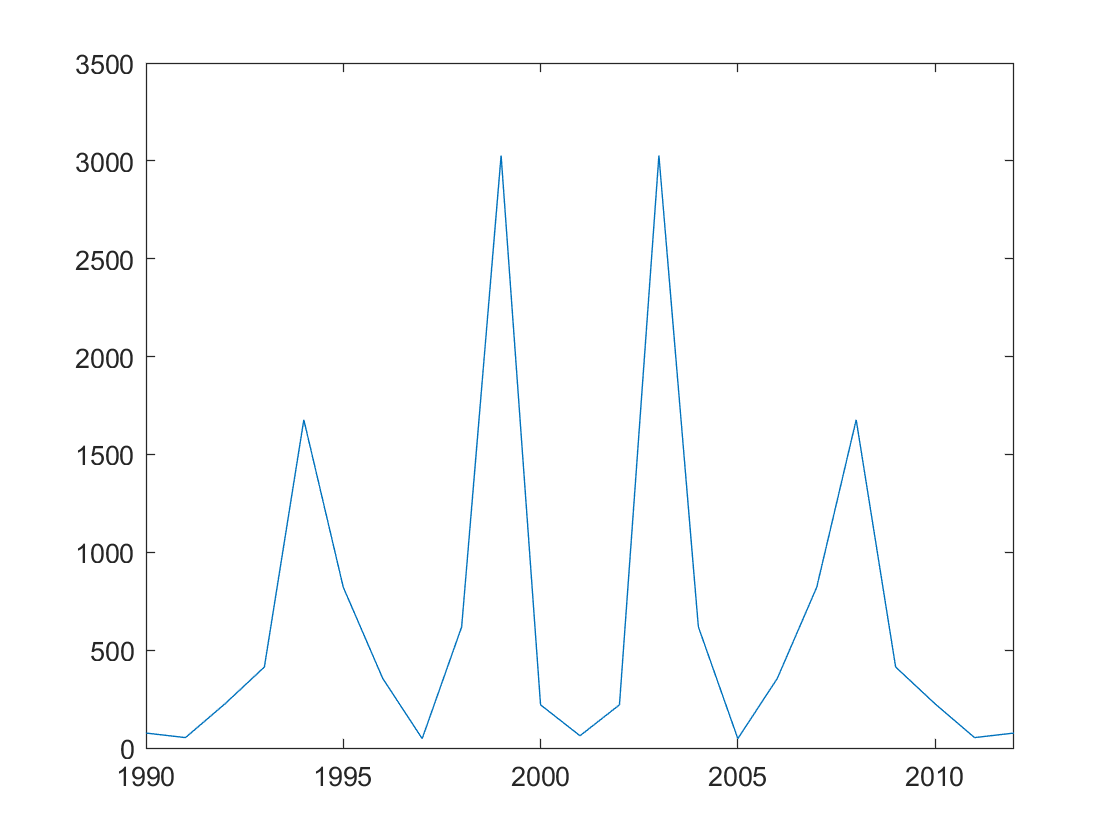


% apply the filter
Y = H .* X;
% see the frequency domain result
plot(abs(fftshift(X)))
xlim([2001-11,2001+11])

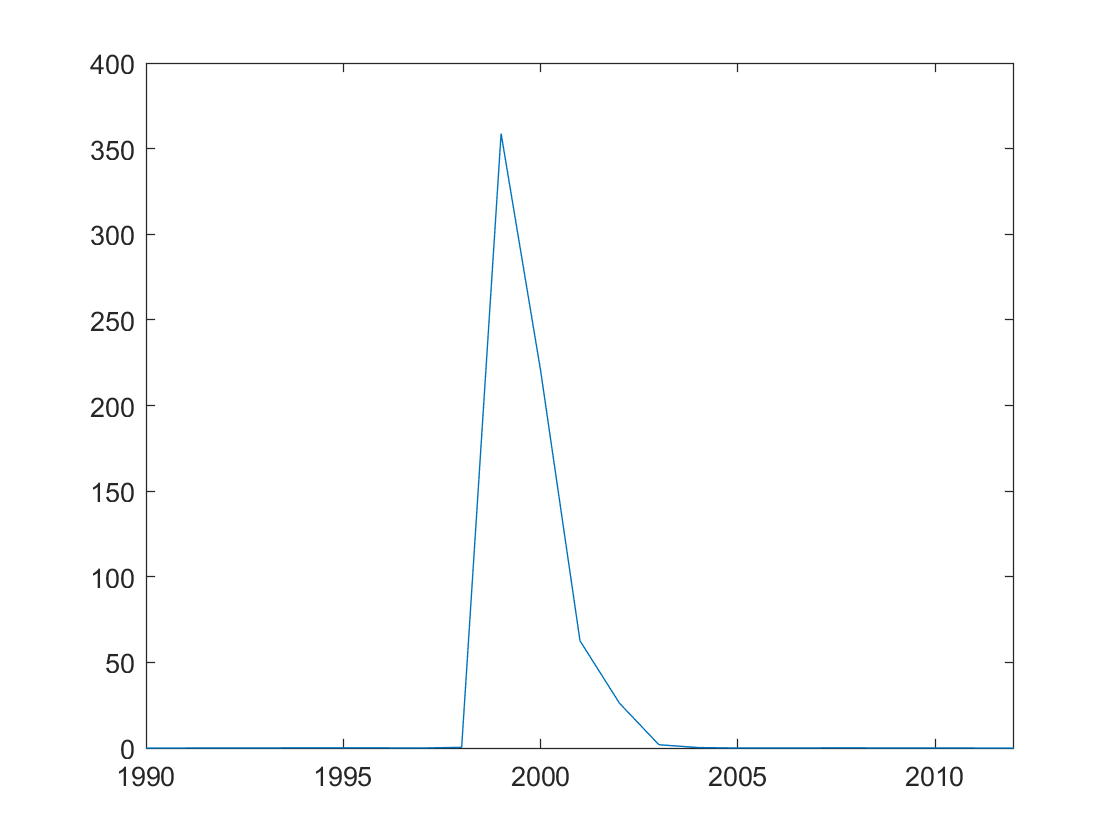

plot(abs(fftshift(Y)))
xlim([2001-11,2001+11])

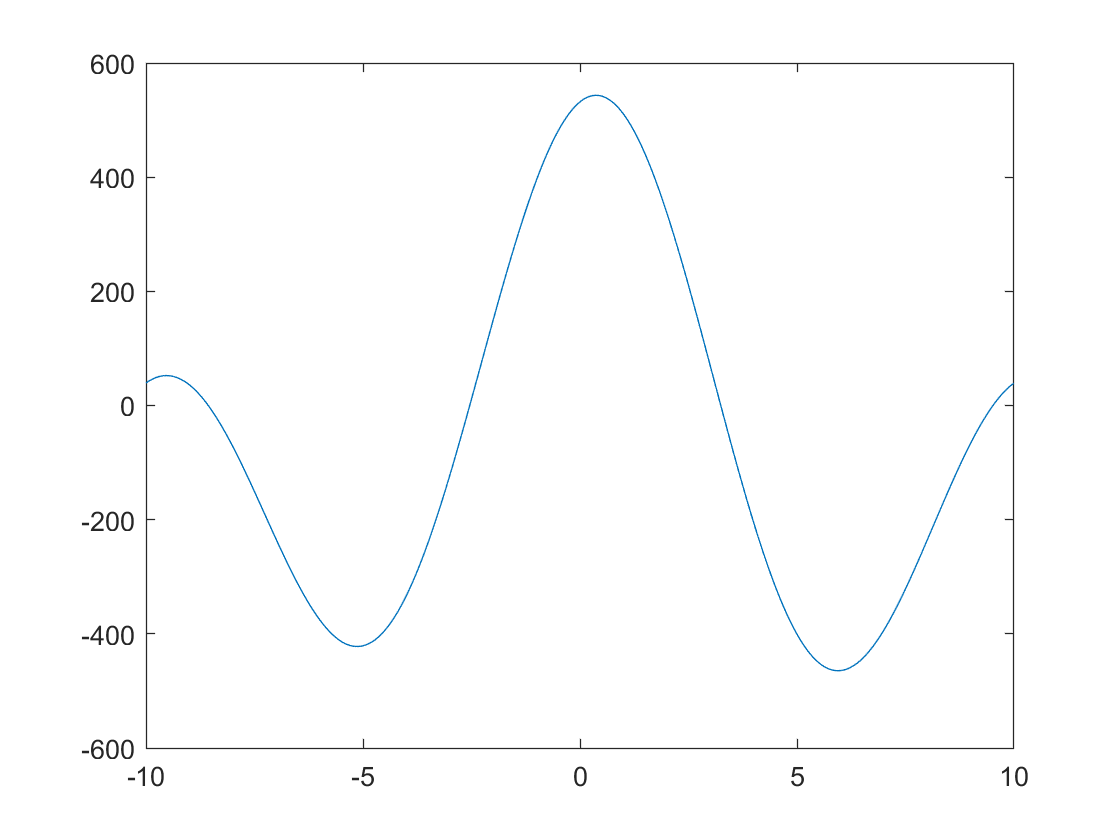


% plot the output and compare it to the ideal output
y = real(fft(Y));
plot(n, y)

%compare that to the ideal signal
plot(n, x1)

This blackman filter does an okay job of extracting x1 from the signal. It doesn't have the issues that the hamming filter had where some of x2 can also be seen. Instead, there is a little bit of an asymetry that was produced due to the filter transferr function being centered at 2000.5, while the function X is centered at 2001.

Finally, lets extract x1 using a kaiser window

% figure out the filter's parameters
n = -10:T:10-T;
wp = (2)*atan((pi/6)*T/2)

wp = 0.0026

ws = (2)*atan((pi/4)*T/2)

ws = 0.0039

wc = pi*12.5/25%(wp + ws) / 2 +0.01

wc = 1.5708

% we can approximate the window length as M = 8*pi/wc
M = length(n)%8*pi / wc

M = 4000

alpha = (M-1)/2

alpha = 1.9995e+03

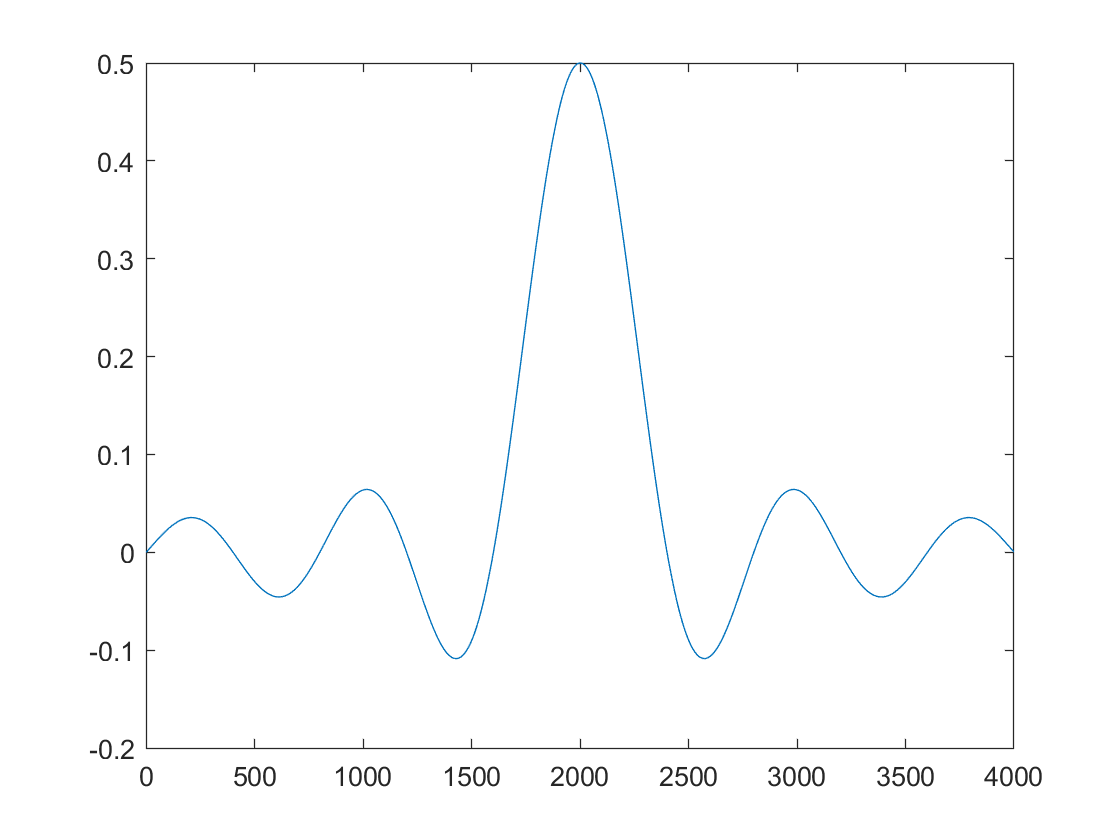



% desired low pass filter
nhd = -10:20/M:10 - 20/M;
hd = (sin(wc*(nhd)))./(pi*(nhd));
plot(hd)

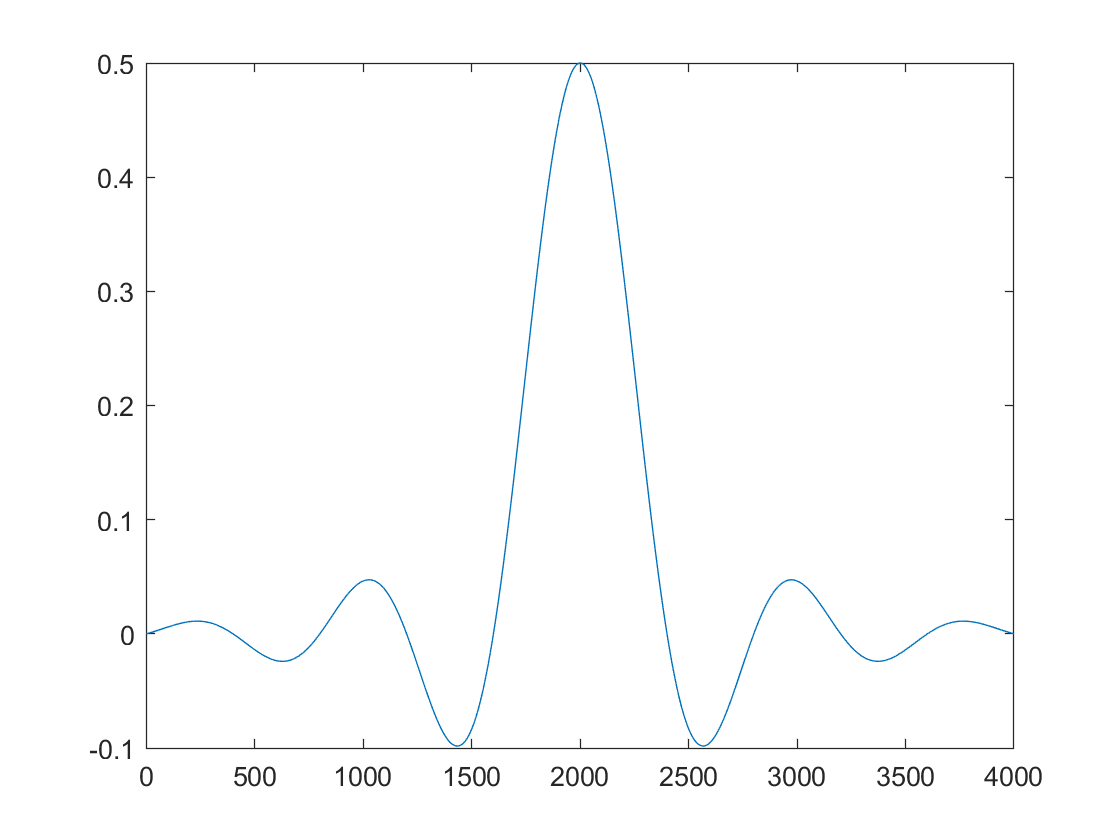

% blackman window
wb = kaiser(M, 3);
% new blackman low pass filter
hn = wb' .* hd;
plot(hn)

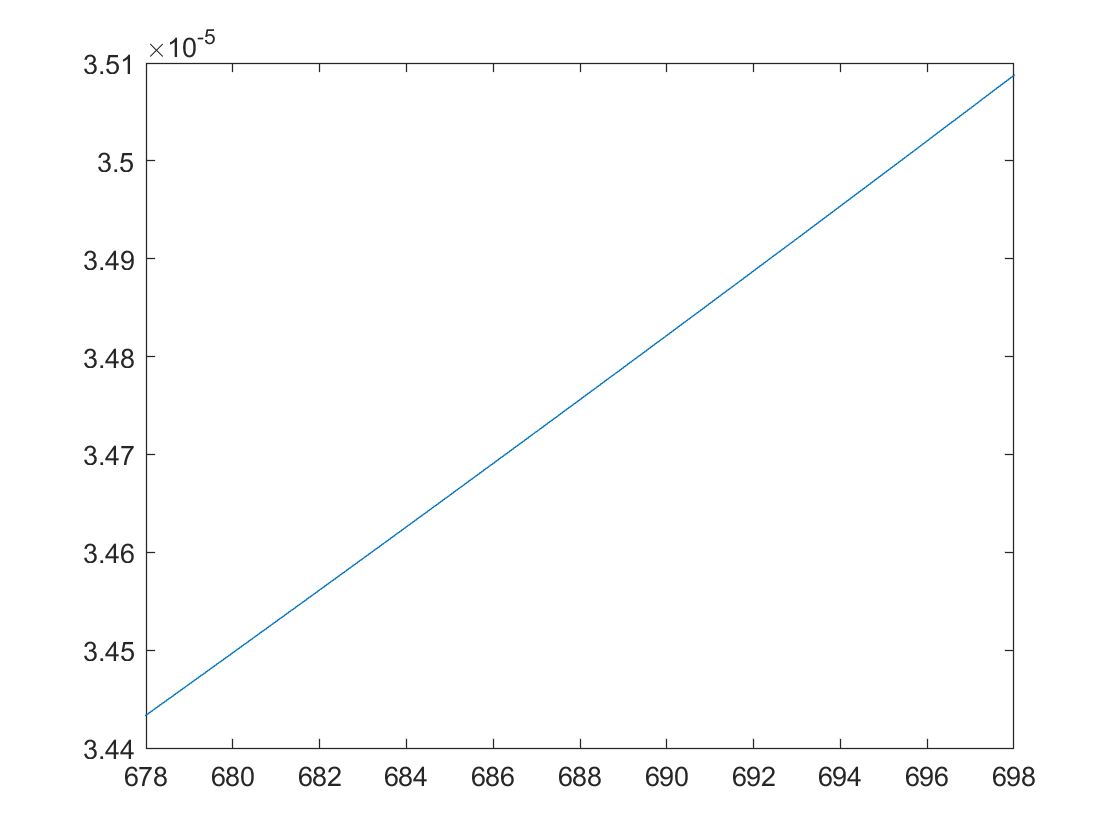

plot(abs(fftshift(fft(hn))))
xlim([688-10, 688+10])

% convert to frequency domain
H = freqz(hn,1,length(n)/2);
%convert the filter from the z domain to the frequency domain
H = H';
H = fftshift([fliplr(H) H]/max(H));

hn = fft(hn)

hn = 	1.0e+02 *

   2.0155 + 0.0000i  -1.9841 + 0.0000i   2.0171 + 0.0000i  -1.9823 + 0.0000i   1.9740 + 0.0001i  -0.9959 - 0.0003i   0.0342 + 0.0001i  -0.0092 + 0.0000i  -0.0082 + 0.0000i  -0.0064 + 0.0000i  -0.0050 + 0.0000i  -0.0040 + 0.0000i  -0.0033 + 0.0000i  -0.0028 + 0.0000i  -0.0023 + 0.0000i  -0.0020 + 0.0000i  -0.0018 + 0.0000i  -0.0015 + 0.0000i  -0.0014 + 0.0000i  -0.0012 + 0.0000i  -0.0011 + 0.0000i  -0.0010 + 0.0000i  -0.0009 + 0.0000i  -0.0008 + 0.0000i  -0.0007 + 0.0000i  -0.0007 + 0.0000i  -0.0006 + 0.0000i  -0.0006 + 0.0000i  -0.0005 + 0.0000i  -0.0005 + 0.0000i  -0.0005 + 0.0000i  -0.0004 + 0.0000i  -0.0004 + 0.0000i  -0.0004 + 0.0000i  -0.0004 + 0.0000i  -0.0003 + 0.0000i  -0.0003 + 0.0000i  -0.0003 + 0.0000i  -0.0003 + 0.0000i  -0.0003 + 0.0000i  -0.0003 + 0.0000i  -0.0002 + 0.0000i  -0.0002 + 0.0000i  -0.0002 + 0.0000i  -0.0002 + 0.0000i  -0.0002 + 0.0000i  -0.0002 + 0.0000i  -0.0002 + 0.0000i  -0.0002 + 0.0000i  -0.0002 + 0.0000i


hn = hn / max(hn)

hn =    0.9992 - 0.0000i  -0.9837 + 0.0000i   1.0000 + 0.0000i  -0.9828 + 0.0000i   0.9787 + 0.0000i  -0.4937 - 0.0001i   0.0169 + 0.0000i  -0.0046 + 0.0000i  -0.0041 + 0.0000i  -0.0032 + 0.0000i  -0.0025 + 0.0000i  -0.0020 + 0.0000i  -0.0016 + 0.0000i  -0.0014 + 0.0000i  -0.0012 + 0.0000i  -0.0010 + 0.0000i  -0.0009 + 0.0000i  -0.0008 + 0.0000i  -0.0007 + 0.0000i  -0.0006 + 0.0000i  -0.0005 + 0.0000i  -0.0005 + 0.0000i  -0.0004 + 0.0000i  -0.0004 + 0.0000i  -0.0004 + 0.0000i  -0.0003 + 0.0000i  -0.0003 + 0.0000i  -0.0003 + 0.0000i  -0.0003 + 0.0000i  -0.0003 + 0.0000i  -0.0002 + 0.0000i  -0.0002 + 0.0000i  -0.0002 + 0.0000i  -0.0002 + 0.0000i  -0.0002 + 0.0000i  -0.0002 + 0.0000i  -0.0002 + 0.0000i  -0.0002 + 0.0000i  -0.0001 + 0.0000i  -0.0001 + 0.0000i  -0.0001 + 0.0000i  -0.0001 + 0.0000i  -0.0001 + 0.0000i  -0.0001 + 0.0000i  -0.0001 + 0.0000i  -0.0001 + 0.0000i  -0.0001 + 0.0000i  -0.0001 + 0.0000i  -0.0001 + 0.0000i  -0.0001 + 0.0000i


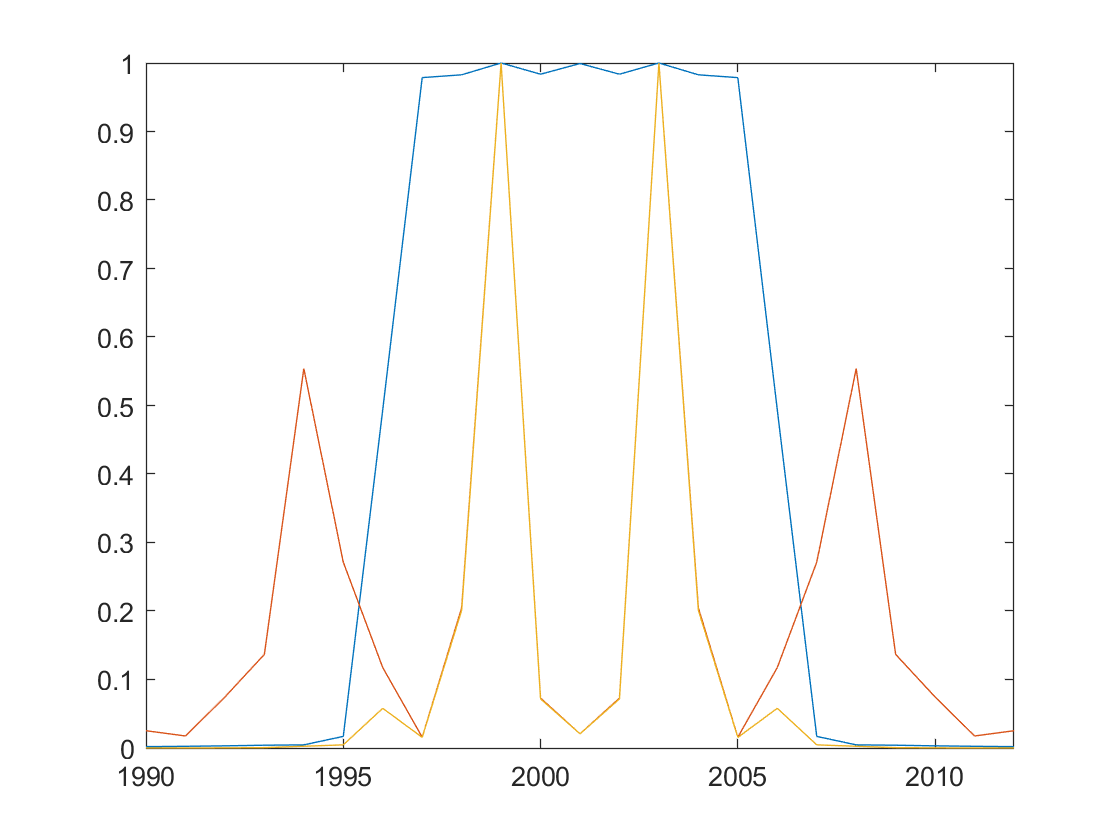

% plot the filter
plot(abs(fftshift((hn))))
xlim([2001-11,2001+11])

% apply the filter
Y = hn .* X;
% see the frequency domain result
hold("on")
plot(abs(fftshift(X)) / max(abs(X)))
xlim([2001-11,2001+11])
plot(abs(fftshift(Y)) /max(abs(Y)))
xlim([2001-11,2001+11])
hold("off")

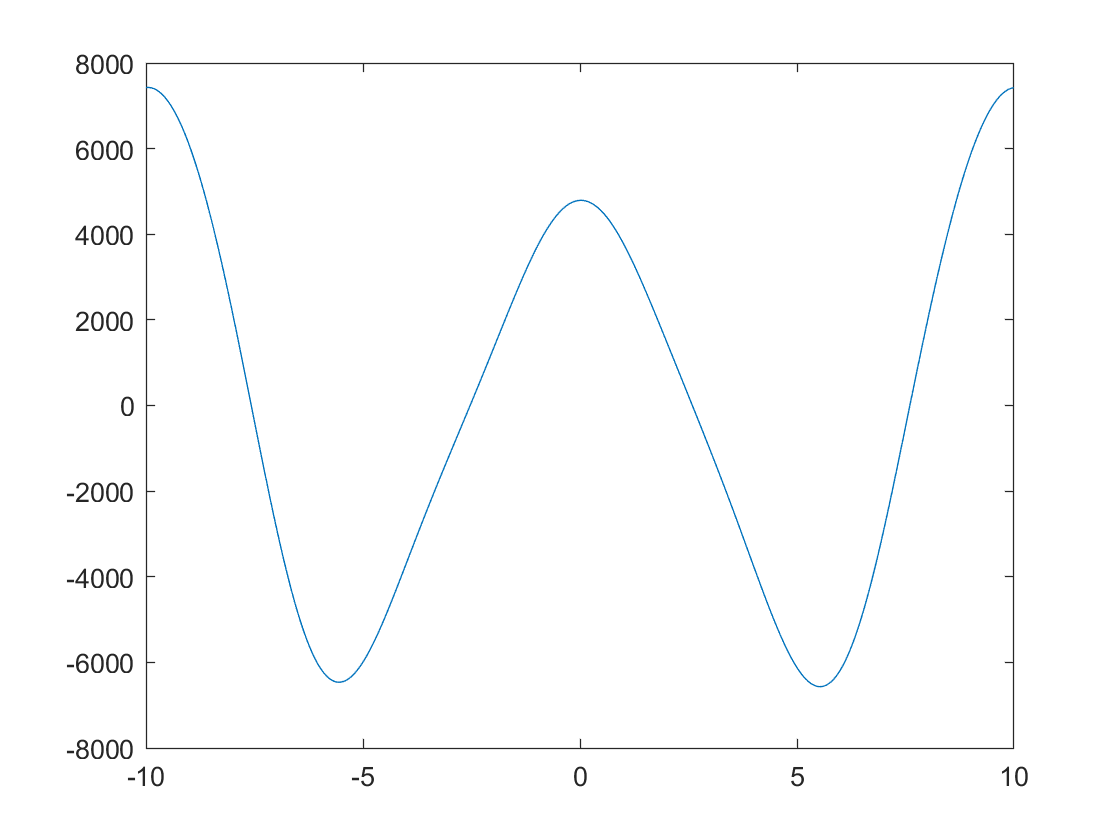


% plot the output and compare it to the ideal output
y = real(fft(Y));
plot(n, y)


%compare that to the ideal signal
plot(n, x1)

This filter also does a relatively good job of getting rid of x2 and x3 while leaving x1 relatively intact.

#### Part D) Use an elliptic, butterworth or chebyshev filter to extract x1

% normalized cutoff frequency

wp = 0.0031

ws = 0.0039

wc = 0.225/(Fs/2)

wc = 0.0023


% create a bbutterworth transfer function
[b,a] = butter(6,wc);

% plot the transfer function magnitude and phase
[h,w] = freqz(b,a,[],Fs)

h =    1.0187 + 0.0000i
  -0.6874 + 0.6012i
   0.0252 - 0.0264i
  -0.0002 - 0.0032i
  -0.0002 - 0.0005i
  -0.0001 - 0.0001i
  -0.0000 - 0.0000i
  -0.0000 - 0.0000i
  -0.0000 - 0.0000i
  -0.0000 - 0.0000i


w =          0
    0.1953
    0.3906
    0.5859
    0.7812
    0.9766
    1.1719
    1.3672
    1.5625
    1.7578


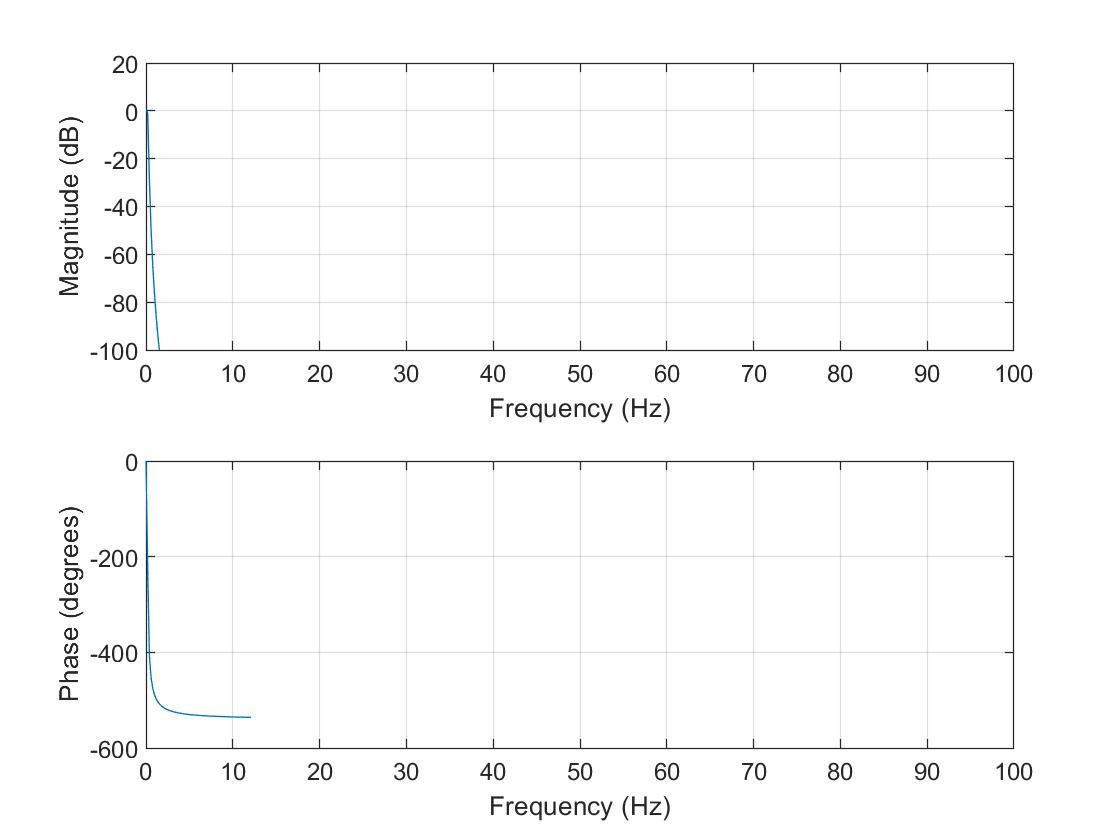

freqz(b,a,[],Fs)
subplot(2,1,1)
ylim([-100 20]);

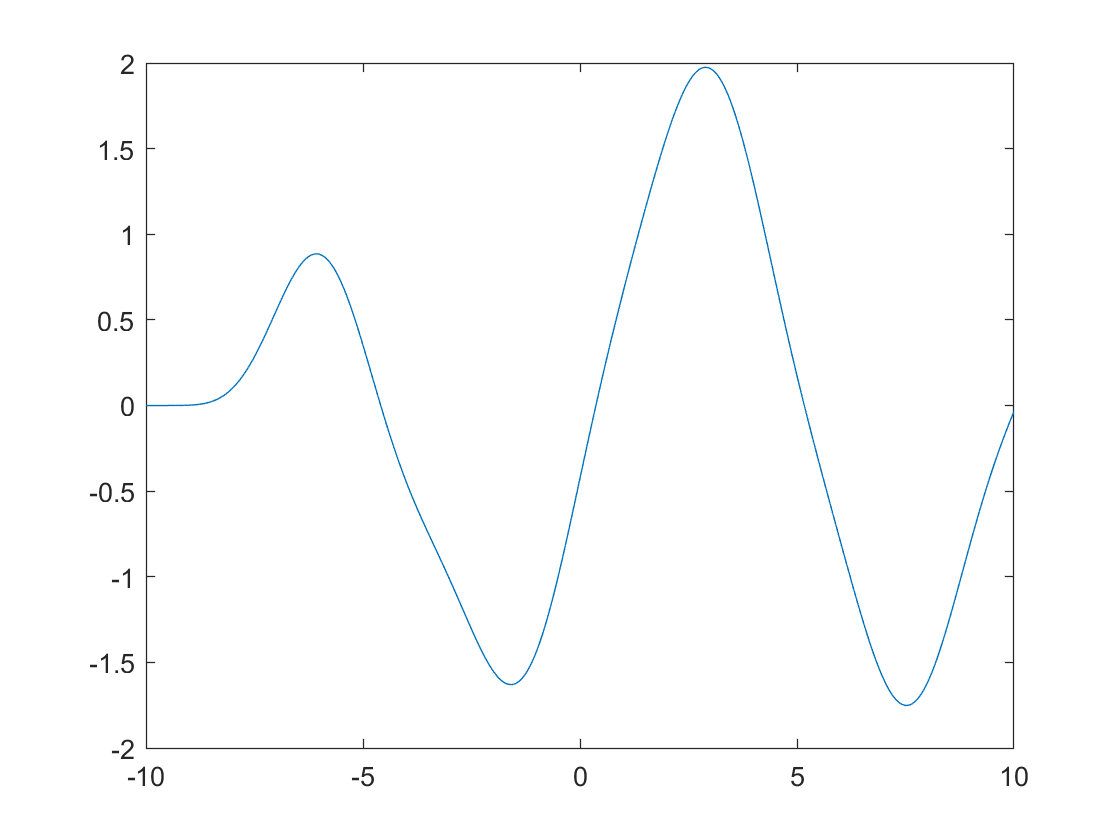

figure;

% filter the input signal with the transfer function
y = filter(b,a,x);
% plot the filtered signal
plot(n,y)

% plot the ideal signal
plot(n,x1)

The filter takes a little bit of time to take effect and become accuract. This can be seen at time between -10 and 0. However, after that, the filter is very accuracte and perfectly recovers the input signal x1. (with a little phase shift)